# Fault Identification in Simulink

This example demonstrates how to estimate one-step delayed unknown inputs and zero-step states of a discrete-time, linear time-invariant (LTI) plant using the ULISE algorithm [1] in Simulink®. You will use the ULISE Filter and LTI Plant blocks to identify the faults (unknown inputs or disturbances) and states [2].

### Introduction:

In this example, we estimate 3 faults and 5 internal states of a discrete-time LTI system. 

The estimator identifies faults (unknown inputs) with a **one-step delay** $d_{k-1} \in \mathbb{R}^3$, while the state vector $x_k \in \mathbb{R}^5$ is estimated with **zero-step delay** [1].

The Simulink model shown below implements this setup.

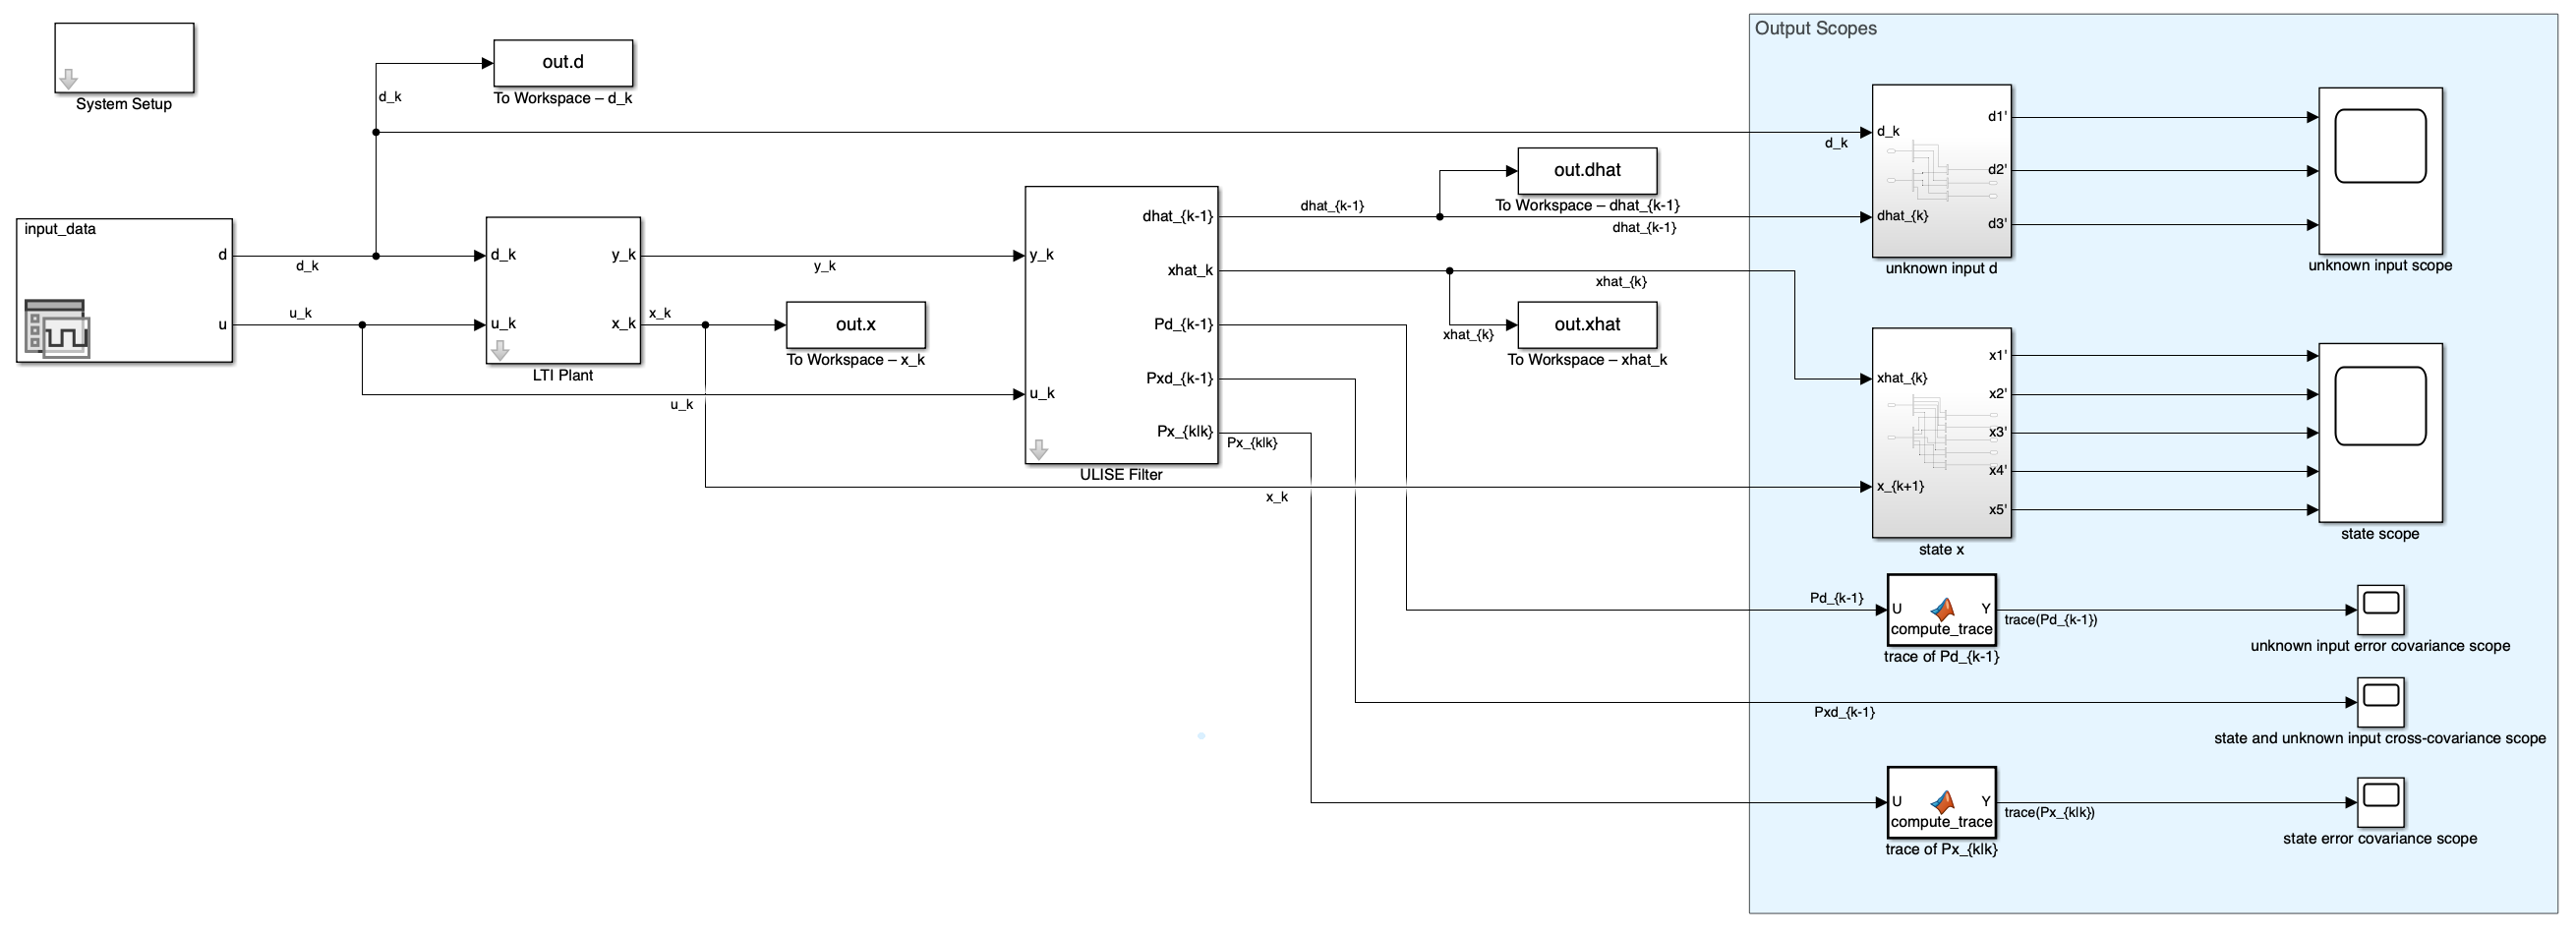

Figure 1: Simulink model of a discrete-time LTI plant using the ULISE filter to estimate current states and one-step delay unknown inputs. 

In general, the Simulink workflow will consist of three main components: 

- **Define system and simulation parameters inside the initialization callback script with the **[**System Setup**](matlab:open('System_setup_Block_overview.mlx'))** block.**

The file [`initFcn_ULISE_faultIdentification.mlx`](matlab:open('initFcn_ULISE_faultIdentification.mlx')) sets the system matrices, noise covariances, initial conditions, total time steps, and sample time used by the LTI Plant and ULISE Filter blocks. 

- **Simulate the system using the **[**LTI Plant**](matlab:open('LTI_Plant_Block_overview.mlx'))** block. **

- **Estimate the states and unknown inputs using the the **[**ULISE Filter**](matlab:open('ULISE_Filter_Block_overview.mlx'))** block.**

Open the Simulink model:

open_system("simulink/ulise/ULISE_faultIdentification_model.slx");

### LTI Plant Model:

The fault identification example is based on a discrete-time, linear time-invariant (LTI) system. The system dynamics and measurement equation are defined as:

$x_{k+1} = A x_k + G d_k + w_k$,


$$y_k = C x_k + H d_k + v_k$$


where $x_k 
$ is the state vector, $d_k 
$ is the unknown inputs, $y_k 
$ is the measured outputs, $w_k 
$ is the process noise, and $v_k 
$ is the measurement noise. In this example, there are no known inputs. 

The process noise and measurement noise are zero-mean vectors and uncorrelated i.e., $\mathbb{E}[w_k v_k^T] = 0$, with error covariances $\mathbb{E}[w_k w_k^T]  = Q \succeq 0$ and $\mathbb{E}[v_k v_k^T] = R \succ 0$, respectively. 

The plant is implemented in the Simulink model using the LTI Plant block, which generates the measured outputs and $y_k$ and states $x_k$.

The system and noise matrices $A$, $C$, $G$, $H$, $Q$, and $R$ have the values:

$A = \left[ \matrix{0.5 & 2 & 0 & 0 & 0 \cr 0 & 0.2 & 1 & 0 & 1 \cr 0 & 0 & 0.3 & 0 & 1 \cr 0 & 0 & 0 & 0.7 & 1 \cr 0 & 0 & 0 & 0 & 0.1} \right]$; $C = \left[ \matrix{1 & 0 & 0 & 0 & 0 \cr 0 & 1 & 0 & 0 & 0 \cr 0 & 0 & 1 & 0 & 0 \cr 0 & 0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 0 & 1} \right]$; 

 $G = \left[ \matrix{ 1 & 0 & -0.3 \cr 1 & 0 & 0 \cr 0 & 0 & 0  \cr  0 & 0 & 0  \cr 0 & 0 & 0} \right]$; $H = \left[ \matrix{ 0 & 0 & 1 \cr 0 & 0 & 0 \cr 0 & 1 & 0  \cr  0 & 0 & 0  \cr 0 & 0 & 0} \right]$;

$Q = 10^{-4} \ \left[ \matrix{1 & 0 & 0 & 0 & 0 \cr 0 & 1 & 0.5 & 0 & 0 \cr 0 & 0.5 & 1 & 0 & 0 \cr 0 & 0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 0 & 1} \right]$; $R = 10^{-2}\ \left[ \matrix{1 & 0 & 0 & 0.5 & 0 \cr 0 & 1 & 0 & 0 & 0.3 \cr 0 & 0 & 1 & 0 & 0 \cr 0.5 & 0 & 0 & 1 & 0 \cr 0 & 0.3 & 0 & 0 & 1} \right]$.

### ULISE Filter Design

The ULISE filter algorithm [1] computes the following estimates given the available measurements $y_k 
$ of a LTI system:

- $\hat{x}_k$: zero-step delay estimate of the state vector

- $\hat{d}_{k-1}$: one-step delay estimate of the unknown input vector.

The ULISE Filter block performs these estimations by assuming the same discrete-time LTI model structure defined in the `initFcn_ULISE_faultIdentification.mlx` script.

The ULISE algorithm can ensure unbiased state estimation if the three Assumptions, described in the ULISE Filter block documentation, are satisfied.

The filter implemented in the Simulink block, during initialization, checks Assumption (i), if the *Control System Toolbox* is installed, and it always checks Assumption (ii). 

### LTI Plant and ULISE Filter Block Inputs and Setup:

All parameters are loaded from the `initFcn_ULISE_faultIdentification.mlx` script. Enter the variable names exactly as they are defined in that script. 

#### **LTI Plant**

Click on the LTI Plant block and under the **Model Parameters** heading, please specify the following system and noise matrices: 

- **A**`: System.A`. The $A$ matrix is defined earlier in this example. 

- `B: ``System.B`. The $B$ matrix is defined as a $5$-by-$1
$ empty vector.

- `C``: System.C`. The $C$ matrix is defined earlier in this example. 

- `D: ``System.D`. `T`he $D$ matrix is defined as a $5$-by-$1
$ empty vector.

- `G: ``System.G`. The $G$ matrix is defined earlier in this example. 

- `H: ``System.H`. The $H$ matrix is defined earlier in this example. 

- **Q:** `System.Q`. The process noise covariance $Q$ is defined earlier in this example.

- **R:** `System.R`. The measurement noise covariance $R$ is defined earlier in this example. 

- `Initial State x_0: ``System.x0`. This represents the initial guess of $x_0$ as a $5$-by-$1$ zero vector.

- `Sample time (-1 for inherited): ``SimSetup.Ts`, which has the default value of 1 second.

Please see the image below. 

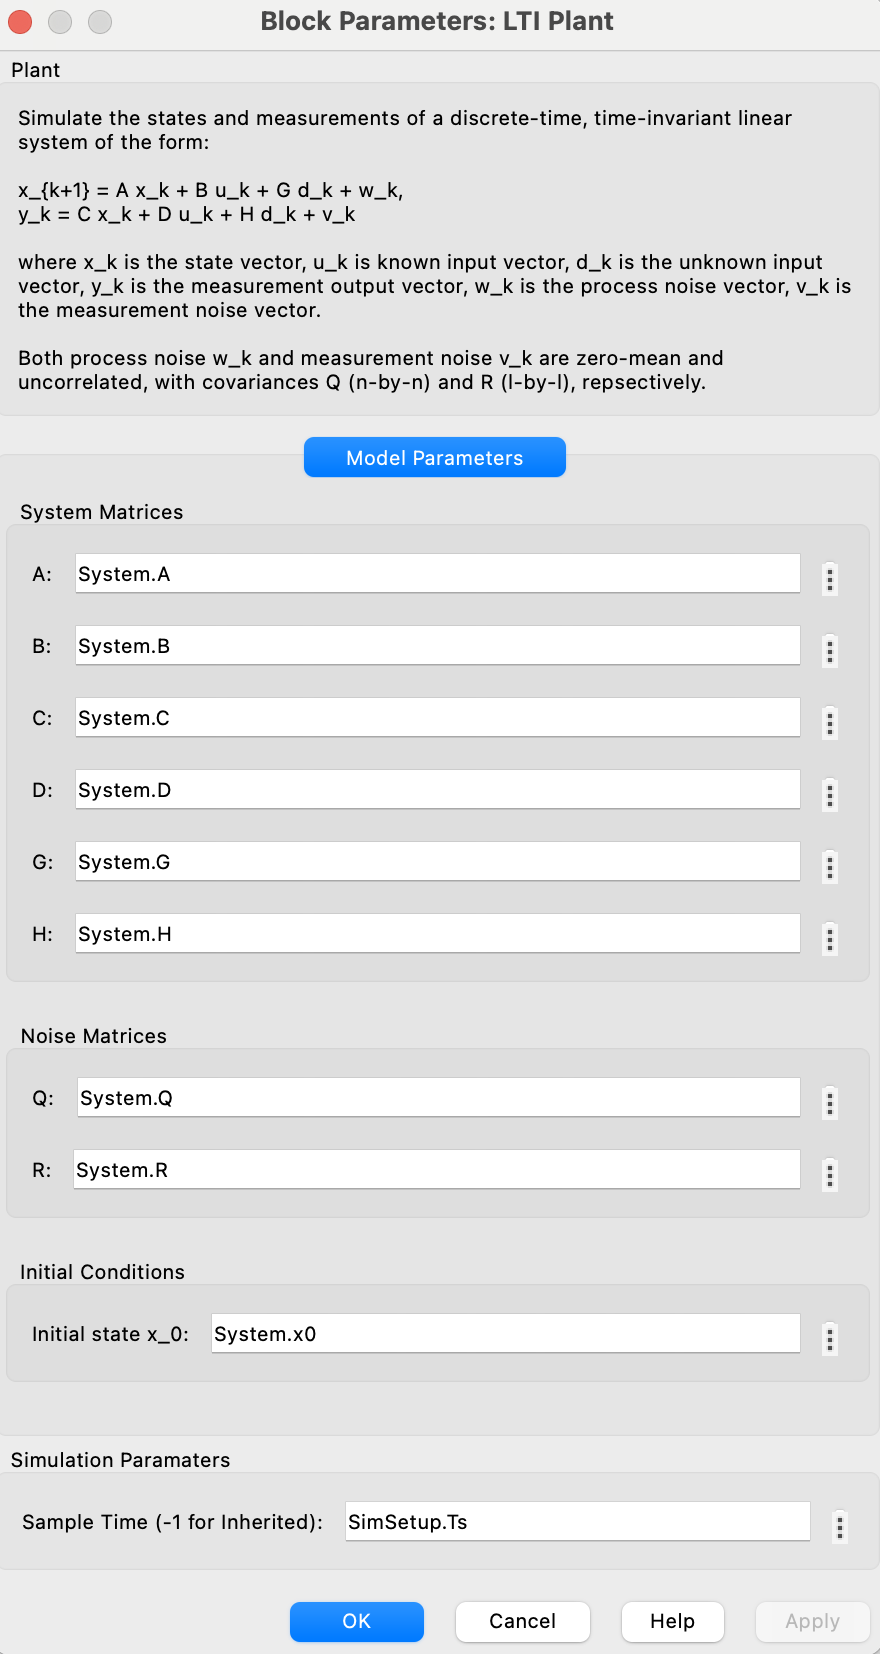

Figure 2: Screenshot of the mask of the LTI Plant block.

#### **ULISE Filter block**

Click on the ULISE FIlter block and under the section **Model Parameters** heading, specify the following system and noise matrices:

- **A**`: System.A`. The $A$ matrix is defined earlier in this example. 

- `B: ``System.B`. The $B$ matrix is defined as a $5$-by-$1
$ empty vector.

- `C``: System.C`. The $C$ matrix is defined earlier in this example. 

- `D: ``System.D`. `T`he $D$ matrix is defined as a $5$-by-$1
$ empty vector. 

- `G: ``System.G`. The $G$ matrix is defined earlier in this example. 

- `H: ``System.H`. The $H$ matrix is defined earlier in this example.

- **Q:** `System.Q`. The process noise covariance $Q$ is defined earlier in this example.

- **R:** `System.R`. The measurement noise covariance $R$ is defined earlier in this example. 

- `Initial State Estimate xhat_0``: System.xhat0`. This represents the initial estimate of the state $\hat{x}_{0|0}$ to be a $5$-by-$1$ zero vector.

- **I**`nitial State Error Covariance Px_0``: System.P_x0`.  This represents the intial state error covariance $P^x_{0|0}$ to be a zero matrix of size $5$-by-$5
$.

- `Sample time (-1 for inherited)``: SimSetup.Ts`, which is defined earlier in this example.

Please see the image below.

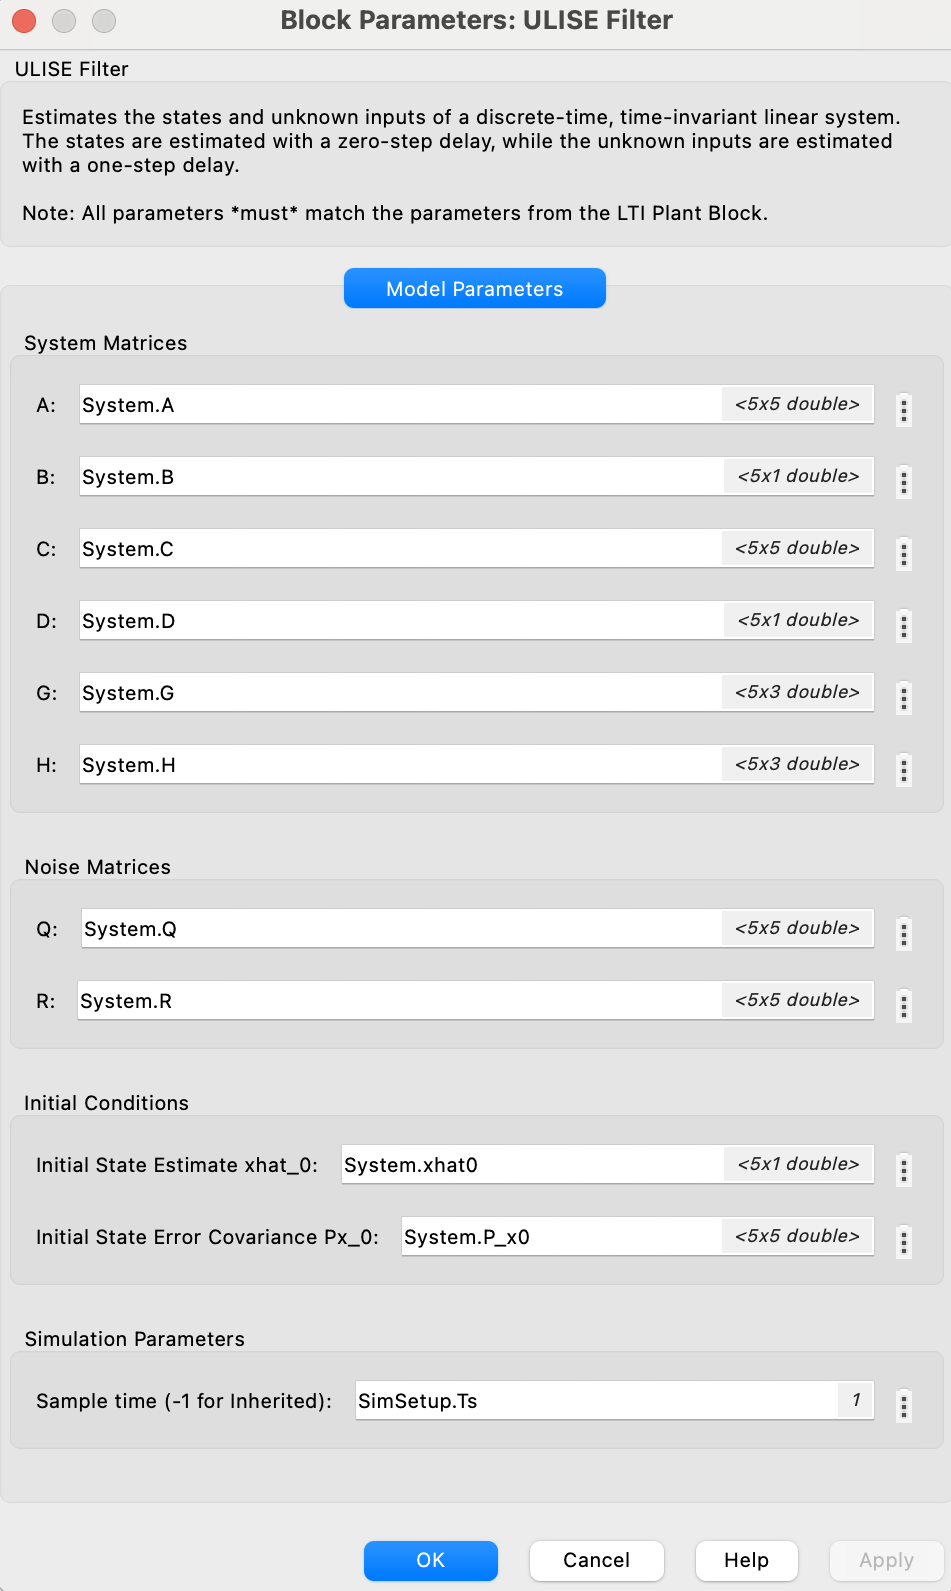

Figure 3: Screenshot of the mask of the ULISE Filter block.

### Results (saved to workspace): 

sim_out = sim("simulink/ulise/ULISE_faultIdentification_model.slx");

### Summary:

This example demonstrated fault identification for a discrete-time, linear time-invariant system. 

The ULISE Filter block accurately estimated the system's states and one-step delayed unknown inputs, and performance was validated through comparison with the true values and their covariance traces. 

bdclose("simulink/ulise/ULISE_faultIdentification_model.slx");

Saving to: ./Examples/Simulink/ULISE_default_signals.mat 


t_zeros =     0.3000
    0.8000


### References:

[1] Yong, S. Z., Zhu, M., & Frazzoli, E. (2016). *A unified filter for simultaneous input and state estimation of linear discrete-time stochastic systems.* *Automatica, 63,* 321–329. [https://doi.org/10.1016/j.automatica.2015.10.040](https://doi.org/10.1016/j.automatica.2015.10.040) 

*(Also available as a preprint at *[*https://arxiv.org/abs/1309.6627*](https://arxiv.org/abs/1309.6627?utm_source=chatgpt.com)*)*

[2] Keller, J. Y., Summerer, L., Boutayeb, M., & Darouach, M. (1996). Generalized likelihood ratio approach for fault detection in linear dynamic stochastic systems with unknown inputs. International journal of systems science, 27(12), 1231-1241.

D. Lawson, S. Macero, E. Gah, and S.Z. Yong (2025). SISE Toolbox for MATLAB (https://github.com/dalawson0/SISE/), GitHub.